### Loading the Dataset

**Description**: This block code loads the measurements accesible in [[2]](https://ieee-dataport.org/documents/dataset-macroscale-molecular-communication-testbed). The csv file has to be stored in the local PC and its path added with the addpath function, as the example below. The measurements are used as the average received sequence

Inputs:

- csv file: This file stores the measurements conducted with the testbed in Fig. 1, and accessible in [[1]](https://ieee-dataport.org/documents/dataset-macroscale-molecular-communication-testbed).

Outputs:

- `measurements`: Matrix array storing the measurements in the columns, except for the first column; which refers to time.

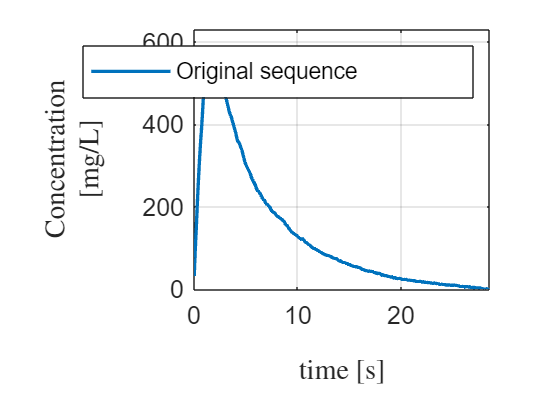

load testbed_pulse.mat %this mat files comprises the recording of a single pulse emitted by the sprayer in Fig. 1 
%%Uncomment the lines below to load the dataset
% %Update the path to your dataset in the argument to the function below
% addpath('../../data/hofmann2023dataset')
% %file data
% data_file ={'dataset_SISO_testbed.csv'};
% %uncomment the lines below to load the dataset

% opts=detectImportOptions(data_file{1});
% preview(data_file{1},opts) %data file preview
% 
% measurements=readmatrix(data_file{1},opts);
% [total_samples,total_measurements]=size(measurements);
% time=measurements(:,1);

**Processing**

**Description**: This block cleans up the received sequence by deleting the transient time at the beginning.

Inputs:

- `measurements`: Matrix array storing the measurements in the columns, except for the first column; which refers to time.

- `select_measurement`: variable to select the column vector in `measurements` to process

Outputs:

- `pulse`: vector array that stores the processed sequence.

% y_end=measurements(end,select_measurement);
% x_init=find(measurements(:,select_measurement)>=y_end,1);
% pulse=measurements(x_init:end,select_measurement)-min(measurements(x_init,select_measurement),measurements(end,select_measurement));
% pulse_duration=length(pulse)*sampling_time;

### Plotting dataset sequence

%plotting
time=(0:length(pulse)-1)*sampling_time;
plot(time,pulse,'LineWidth',2);grid on;
xlabel('time [s]','Interpreter','latex');
ylabel({'Concentration','[mg/L]'},'Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([time(1) time(end) 0 1.1*max(pulse)]);
legend('Original sequence','Processed sequence');

### Emissions

**Description:** This block performs the reception of a random sequence of bits. The operation is performed using the above pulse sequence as the average sequence reception for a transmitted bit-1. This average sequence is used with the Poisson model, see [3, Eq. (87)],  performing the random reception of bits.

Inputs:

- `total_bits`: Amount of bits to transmitt as specified in the Parameters section.

- `T_b`: Bit duration.

- `sampling_time`: sampling time as defined by the testbed.

- `r_int`: amount of interference as specified in the Parameters section.

Outputs:

- `Rx_samples`: Vector array that stores the received sequence.

- `L`: Channel memory.

- SNR: Evaluated SNR parameter.

bits=randi([0,1],total_bits,1);

SNR=27.5


% bits=[1 0 1 0 1];
Tx_impulses=zeros(1,ceil(T_b/sampling_time)*total_bits);
Tx_pulses=zeros(1,ceil(T_b/sampling_time)*total_bits);

for i=1:total_bits
    x1=(i-1)*ceil(T_b/sampling_time)+1;
    x2=x1+ceil(T_b/sampling_time)-1;
    Tx_impulses(x1)=bits(i);
    Tx_pulses(x1:x2)=ones(1,ceil(T_b/sampling_time))*bits(i);
end

%Gaussian model
% seq_Rx_mean=(conv(Tx_impulses,pulse));
% var_noise_dB=30;
% seq_Rx=awgn(conv(Tx_impulses,pulse),var_noise_dB,"measured");

%%channel attenuation
pulse=pulse*A_tt;

%Poisson model
% Evaluating the SNR, see Eq.(88) in [3]
disp(['SNR=',num2str(pow2db(max(pulse)^2/(max(pulse)+r_int)),3)])
%Total of received molecules, see Eq. (87) in [3]
seq_Rx_mean=(conv(Tx_impulses,pulse*A_tt))+1;%we add one to the complete sequence to avoid the NaN outputs from the Poisson distribution in the next line
seq_Rx=seq_Rx_mean+poissrnd(seq_Rx_mean)-poisstat(seq_Rx_mean)+poissrnd(r_int)-poisstat(r_int);


#### Channel memory

L=floor(pulse_duration/T_b);

#### Synchronization signal

[~,loc]=max(pulse);
synch=(0:floor(length(seq_Rx)/T_b*sampling_time)-2)*floor(T_b/sampling_time)+loc;
Rx_samples=seq_Rx(synch);


### Dataset partition

Description: The dataset is created into sets: `input_sequence` and `target_bits`. The `input_sequence` set is a cell of arrays, where each array stores a sequence of received samples after synchronization (`Rx_samples`) of length given by `input_length`. The `target_bits` set is a cell of arrays, each array storing the sequence of emitted bits of length `input_length`. The variable `input_length` is evaluated as the channel memory.

input_length=L;%size of the input data
total_sets=floor(total_bits/input_length);%total of arrays in the data and label cells
%completing the data and label cells
input_sequence=cell(total_sets,1);
target_bits=cell(total_sets,1);

for i=1:total_sets
    x1=(i-1)*input_length+1;
    x2=x1+input_length-1;
    input_sequence{i}=Rx_samples(x1:x2);
    target_bits{i}=bits(x1:x2)';
end



Set aside data for testing. Partition the data into a training set containing 90% of the data and a test set containing the remaining 10% of the data. To partition the data, use the `trainingPartitions` function, attached to this example as a supporting file. To access this file, open the example as a live script.

XTrain = input_sequence;
TTrain = target_bits;

% %Uncomment the lines below for partioning data
% numObservations = numel(input_sequence);
% [idxTrain,idxTest] = trainingPartitions(numObservations, [0.99 0.01]);
% XTrain = input_sequence(idxTrain);
% TTrain = target_bits(idxTrain);
% 
% XTest = input_sequence(idxTest);
% TTest = target_bits(idxTest);

### References

[1] P. Hofmann, J. Torres Gómez, F. Dressler, and F. H. P. Fitzek, “Testbed-based Receiver Optimization for SISO Molecular Communication Channels,” in 5th IEEE International Balkan Conference Communications and Networking (BalkanCom 2022), Sarajevo, Bosnia and Herzegovina: IEEE, Aug. 2022, pp. 120–125.

[2] Pit Hofmann, Jorge Torres Gómez, Frank H. P. Frank H.P. , Falko Dressler, April 27, 2023, "Dataset for Macroscale Molecular Communication Testbed", IEEE Dataport, doi: https://dx.doi.org/10.21227/ytkm-xp81.